# Internal Flow

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

Internal flow is crucial for engineerings as it involves the study of fluid in enclosed system such as pipes and ducts. Understanding internal flow is necessary for designing efficient and effective system for transportation, ventalition and heating system. In [PressureVelocity.mlx](matlab:open('./PressureVelocity.mlx')) we introduced Bernoulli's equation for ideal flow, in this script we will learn how to model internal fluid flow using Bernoulli's equation for non-ideal flow, including pressure loss due to friction.

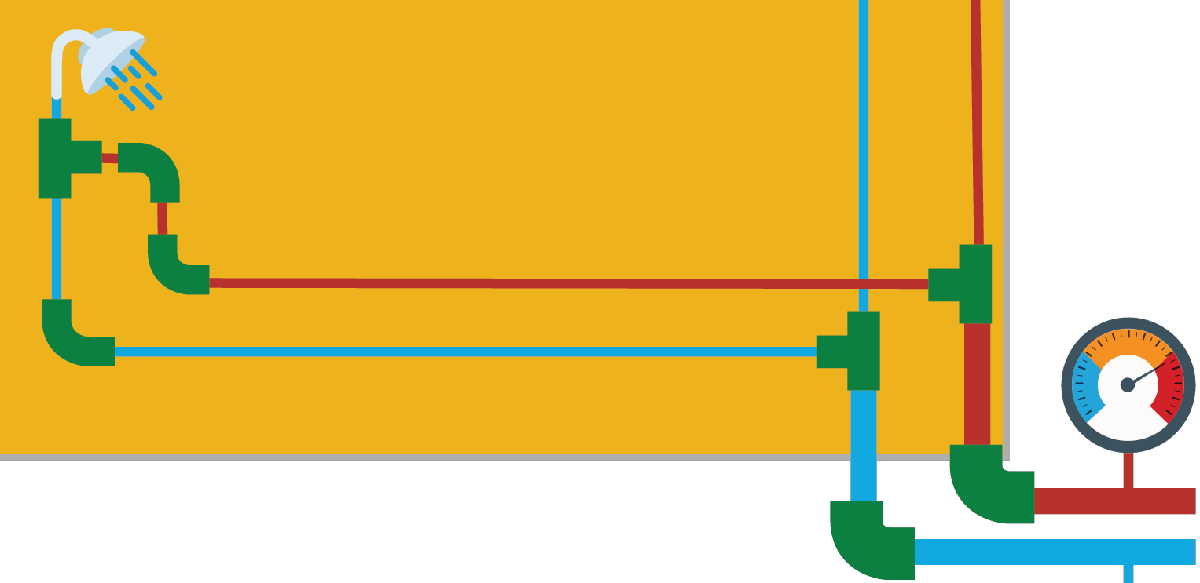

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build somgit e familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understaning of those concepts and may be used for grading and completion checks by your professor.

## Ideal vs. non-ideal internal flow

In [PressureVelocity.mlx](matlab:open('./PressureVelocity.mlx')), we introduced Bernoulli's equation:


$$\frac{P}{\rho g} + \frac{v^2}{2 g} + h = H_0=\text{Constant}
\qquad
(\text{Head-loss form})$$



$$P+
\frac{1}{2}\rho v^2+
\rho g z= \text{Constant} 
\qquad
(\text{Pressure form})$$


This relation states that the total pressure, or total energy of the fluid is conserved along a streamline. This is an idealistic view of fluid flow, and particularly for internal flow, the energy is not conserved. Take the example of a house with its plumbing, the energy of the water flowing through the pipe is not entirely conserved from time it enters the house through the main water intake to the time it leaves the house to the sewer system. For example, in every pipe the friction of water against the wall of the pipe dissipates energy and participe in reducing the pressure. Moreover, every elbow, change in diameter, valve, opening etc. are also associated with dissipation of energy. These dissipation of energy is usually refered as head-loss.

## How to estimate head-loss

### Pipe head-loss

The head-losses due to friction in a pipe are usually defined using the Darcy-Weisbach equation:


$$H_l = f_D \frac{L}{D}\frac{V^2}{2g}
\qquad
(\text{Head-loss form})$$



$$\Delta P = \rho g H_l
\qquad
(\text{Pressure form})$$


Where $L$ is the length of the pipe, $D$ its diameter, $V$ the velocity of the flow and $g$ is the local acceleration due to gravity. The coefficient $f_D$ is Darcy's friction factor. This friction factor has been studied and tabulated experimentally, it is usually expressed as a function of the pipe material and the regime of the flow. In general, the material is defined through a relative roughness ratio $\eta=\frac{\epsilon}{D}$, where $\epsilon$ is the roughness of the pipe (in unit of length) and $D$ is the diameter of the pipe. The regime of the flow is characterize through the Reynolds number:


$$\text{Re} = \frac{\rho VD}{\mu}$$


The Reynolds number is a common dimensionless number that is used in fluid dynamics. In general, high Reynolds number indicates turbulent flow, while low Reynolds number indicates laminar regime. There is [multiple formula](https://en.wikipedia.org/wiki/Darcy_friction_factor_formulae) to calculate the friction coefficient as a function of the Reynolds number and the material roughness. Each formulas are more or less accurate depending on the range of roughness and the regime. 

#### Laminar regime

The head-loss in a pipe in laminar regime was determined anatically by Poiseuille:


$$f_D = \frac{64}{\text{Re}}
\qquad
\text{with Re} < 3000$$


The Reynolds number Re is a non-dimensional number representing the that helps in the characterization of the flow regime. For pipe flow, Reynolds number under 3000 are consider to be laminar.


$$\text{Re} = \frac{\rho VD}{\mu}$$


Where $\rho$ is the density of the fluid, $V$ its velocity, and $\mu$ the dynamic viscosity. $D$ a length-scale that depends on the problem considered, commonly the diamater in case of pipe flow.

#### Turbulent regime

The head-loss in a pipe in turbulent regime can be determined using the Colebrook-White equation:


$$\frac{1}{\sqrt{f_d}} = -2\log\left(\frac{\epsilon}{3.7D_H}+\frac{2.51}{\text{Re}\sqrt{f_D}} \right)
\qquad
\text{with Re} > 4000$$


In this equation, $\frac{\epsilon}{D_H}$ correspond to the relative roughness of the pipe, $\epsilon$ correspond to the roughness and is expressed in units of length (usually mm or inches). The Colebrook-White equation is non-linear and is solved using iterative process. A

  **Try. **Find Darcy's friction coefficient using the Colebrook-White equation

fd = frictionColebrook(21710, 0.043334)

 **Exercise. Which line represent the smooth pipe in turbulent?**

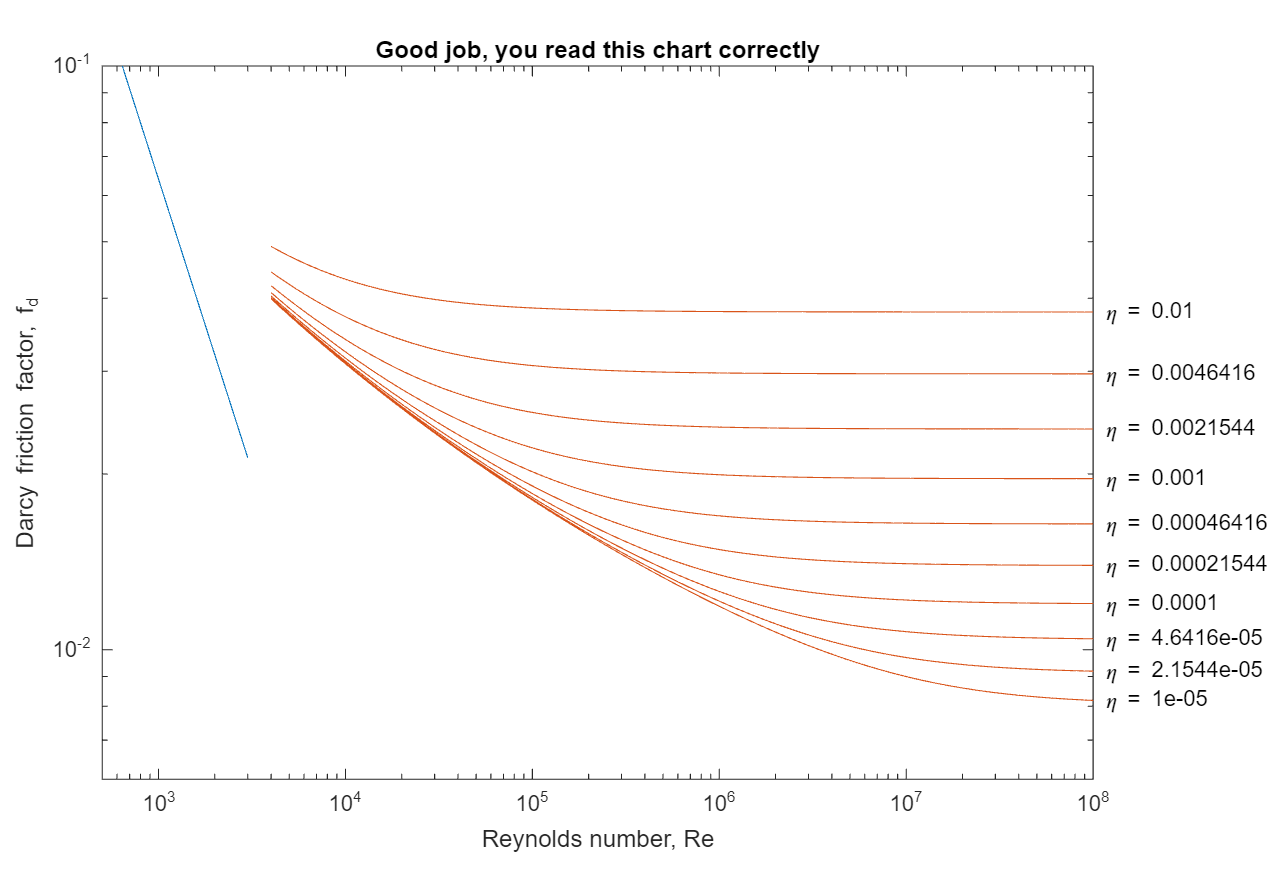

  MoodyPlotExercise

### Minor head loss

Major head losses occurs in pipe due to the friction against the pipe wall. Minor head losses are the head losses that are caused by the disturbance of the flow. Some of the most common head loss comes from fitting such as, but not limited to: elbows, restriction, orifices, and valves. When designing a fluid network, the fittings manufacturer can usually provide tabulated data of the head losses as a function of the fittings parameter and the flow characteristics (Reynolds number). 

In this script, we will use tabulated data from the Simscape fluid library, which are valid for standard piping equipement and can be adjusted to more particular settings. For example, the [documentation page](https://www.mathworks.com/help/hydro/ref/elbowtl.html) of the elbow turn in the thermal liquid library provides a table of the friction factor as a function of the nominal size of the elbow.

## Application to house plumbing

A really common fluid network is the plumbing system in a house. In this section we will model a simple house plumbing considering a shower on both floor of the house and a washer on the second floor.

### Head losses indentification

The first step in modeling any fluid network is to identify what head losses are present.

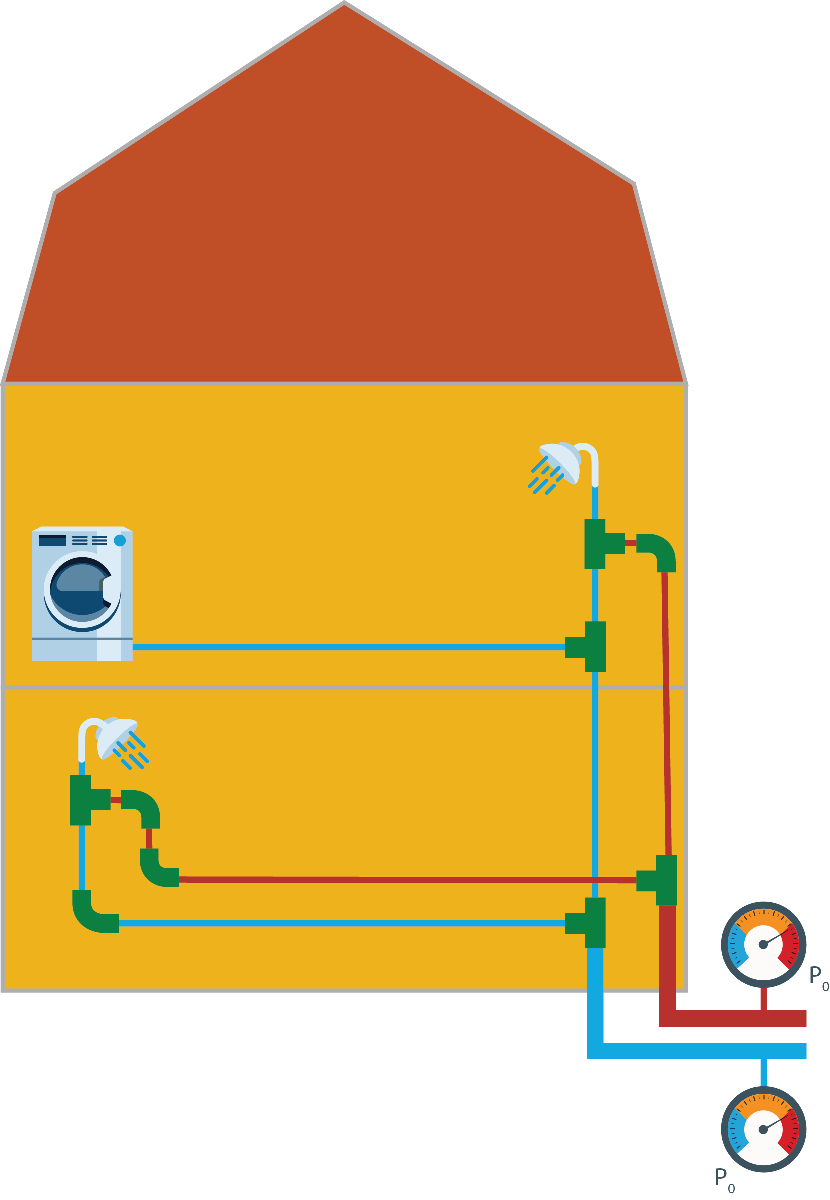

 **Exercise. **Click on the figure below to identify all the head losses

 
IdentifyHeadLoss

### First model

In this section, we are considering a simplified version of the plumbing that does not include the washer and only some of the fittings provided in the previous figures:

 **Exercise. **Intuitively what shower head should have the highest flow rate?

checkMdl1QFlowRate(0)

  **Try. **Open the model and follow the instruction provided

open("House_Mdl1.slx")
 

### Equalizing the network

We are trying to make sure that both shower can provide the same temperature and the same mass flow. There is 

 **Exercise. **What could you do to make sure both shower flows the same way?

checkMdl1Solution(0)

  **Try. **Open the second model and follow the instruction provided.

open("House_Mdl2.slx")
 

### Adding the washer on the network

In this section, we are adding the washed onto the pipping network. When the washer is not running, the flow through both shower head should be unchanged. However, we want to verify that the shower stays confortable when the washer turns on.

 **Exercise. **Intuitively, how would the washer influence the mass flow through the showers?

checkMassFlowWasher(0,0)

 **Exercise. **Intuitively, how would the washer influence the temperature through the showers?

checkTemperatureWasher(0,0)

  **Try. **Open and run the third model.

open("House_Mdl3.slx")
 

You can explore the results from this from the simulation in the Simscape Results app:

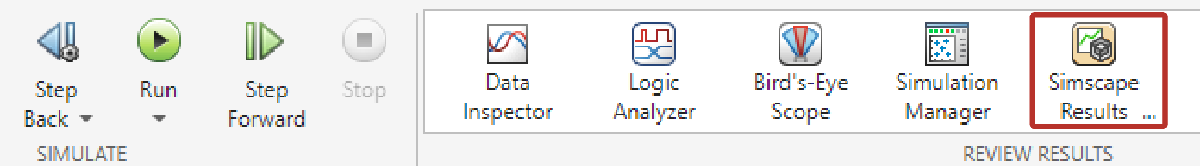

Explore the results of the first and second floor shower and plot the temperature as a function of time.

Both shower are greatly affected when the washer start its washing cycle, so much that it makes the temperature of the shower dangerous to use.

 **Exercise. **What could we do to remidiate this situation?

checkRemediation(0)

  **Try. **Open and run the fourth model

open("House_Mdl4.slx")
 

## Further exploration

This script should have help you to develop some practical intuition of how pipe flow works and how to equilibriate a network. The best way to gain more understanding is practising. The model presented in this script can be modified to your liking to try different scenario. You could try things like this:

- Make the network more complex by adding more fixture such as sink and toilet.

- Play with the dimension of the pipe.

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

## Helper Functions

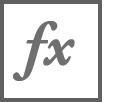`frictionColebrook(Re, eta)`

function fD = frictionColebrook(Re, eta)
    if Re <= 3500
        fD = 64 ./ Re;
    else
        fun = @(f) 1./sqrt(f) + 2*log10( eta/3.7 + 2.51./(Re.*sqrt(f)) );
        fD = fzero( fun, [eps 1]);
    end
end

`MoodyPlotExercise()`

function MoodyPlotExercise()
    % Plot laminar regime:
    Re = logspace(0,log10(3000),100);
    fD = arrayfun(@(x)frictionColebrook(x,0.1),Re);
    pltLaminar = loglog(Re,fD,SeriesIndex=1,DisplayName="Laminar Regime",ButtonDownFcn=@(src,event)LaminarCallback(src));
    
    % plot turbulent:
    Re = logspace(log10(4000),8,100);
    neta = 10;
    eta = logspace(-5,-2,neta);
    hold on
    pltTurbulent = gobjects(10,1);
    for i = 1:neta
        fD = arrayfun(@(x)frictionColebrook(x,eta(i)),Re);
        text(Re(end),fD(end)," \eta = "+num2str(eta(i)))
        pltTurbulent(i) =  loglog(Re,fD,SeriesIndex=2);
    end
    hold off
    
    % Set the axes:
    pltTurbulent(1).ButtonDownFcn = @(src,event)SmoothCallback(src);
    pltTurbulent(end).ButtonDownFcn = @(src,event)RoughCallback(src);
    title("Click on the laminar regime")
    subtitle("Question 1/3")
    xlim([5e2 1e8])
    ylim([6e-3 1e-1])
    ylabel("Darcy friction factor, f_d")
    xlabel("Reynolds number, Re")
    set(gcf,"Position",[740,670,775,530])
    set(gca,"OuterPosition",[-0.05,0.0,1.0,1.0])
end

`LaminarCallback(src)`

function LaminarCallback(src,~)
    if src.Parent.Subtitle.String == "Question 1/3"
        src.Parent.Title.String = "Click on the turbulent smooth pipe";
        src.Parent.Subtitle.String = "Question 2/3";
    end
end

`SmoothCallback(src,~)`

function SmoothCallback(src,~)
    if src.Parent.Subtitle.String == "Question 2/3"
        src.Parent.Title.String = "Click on the turbulent rough pipe";
        src.Parent.Subtitle.String = "Question 3/3";
    end
end

`RoughCallback(src,~)`

function RoughCallback(src,~)
    if src.Parent.Subtitle.String == "Question 3/3"
        src.Parent.Title.String = "Good job, you read this chart correctly";
        src.Parent.Subtitle.String = "";
    end
end

`checkMdl1QFlowRate(answer)`

function checkMdl1QFlowRate(answer)
    arguments
        answer (1,1) double {mustBeMember(answer,[0 1 2])}
    end

    switch answer
        case 0
            warning("Please, select either first or second floor shower.")
        case 1
            disp("Good job! The first floor shower has less head loss from the "+...
                "water intake to the shower head, and therefore should have "+...
                "a higher flow rate.")
        case 2
            warning("The first floor shower has less head loss from the "+...
                "water intake to the shower head, and therefore should have "+...
                "a higher flow rate.")
    end
end

`checkMdl1Solution(answer)`

function checkMdl1Solution(answer)
    arguments
        answer (1,1) double {mustBeMember(answer,0:4)}
    end
    
    switch answer
        case 0
            warning("Select one of the option in the drop down list.")
        case 1
            disp("Good job! We can easily add head loss on the way to the first floor "+...
                "shower head by adding a regulation valve. This valve can be adjusted to "+...
                "equalize the mass flow at both shower head.")
        case 2
            warning("Reducing head loss on the way to the first floor shower would "+...
                "increase the mass flow even more.")
        case 3
            warning("Increasing head loss on the way to the second floor shower would "+...
                "increase the unbalance in the network.")
        case 4
            warning("Reducing the head loss on the way to the second floor whoser would "+...
                "be hard (change of pipe, etc.). You can probably think of an easier way.")
    end
end

`checkRemediation(answer)`

function checkRemediation(answer)
    arguments
        answer (1,1) double {mustBeMember(answer,0:3)}
    end

    switch answer
        case 0
            warning("Select one of the answer.")
        case 1
            warning("Adding a thermostatic valve would be a great solution, "+...
                "and it is a common solution for most house. In this script, we"+...
                " opted for a different solution.")
        case 2
            disp("Good job! The washer as modelled in the previous model is filling"+...
                " up much faster than a regular home washer. In the next model, we will"+...
                " have a washer that fills up slower.")
        case 3
            warning("Filling up the washer faster would only make the situation worse.")
    end
end

`checkTemperatureWasher(answerA, answerB)`

function checkTemperatureWasher(answerA, answerB)
    arguments
        answerA (1,1) double {mustBeMember(answerA,0:3)}
        answerB (1,1) double {mustBeMember(answerB,0:3)}
    end
    
    switch answerA
        case 0
            warning("Select an option for the temperature of the first floor shower.")
        case 1 % decrease
            warning("The temperature would not decrease in the first floor shower.")
        case 3 % unchange
            warning("Any change on the network would affect the temperature.")
    end

    switch answerB
        case 0
            warning("Select an option for the temperature of the second floor shower.")
        case 1 % decrease
            warning("The temperature would not decrease in the second floor shower.")
        case 3 % unchange
            warning("Any change on the network would affect the temperature.")
    end

    if answerA == 2 && answerB == 2
        disp("Good job! Both temperature would increase.")
    end
end

`checkMassFlowWasher(answerA, answerB)`

function checkMassFlowWasher(answerA, answerB)
    arguments
        answerA (1,1) double {mustBeMember(answerA,0:3)}
        answerB (1,1) double {mustBeMember(answerB,0:3)}
    end
    
    switch answerA
        case 0
            warning("Select an option for the mass flow of the first floor shower.")
        case 2 % increase
            warning("The mass flow would not increase in the first floor shower.")
        case 3 % unchange
            warning("Any change on the network would affect the mass flow.")
    end

    switch answerB
        case 0
            warning("Select an option for the mass flow of the second floor shower.")
        case 2 % increase
            warning("The mass flow would not increase in the second floor shower.")
        case 3 % unchange
            warning("Any change on the network would affect the mass flow.")
    end

    if answerA == 1 && answerB == 1
        disp("Good job! Both mass flow would decrease.")
    end
end

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

Copyright 2023 The MathWorks™, Inc